%% mesh

## 起手式

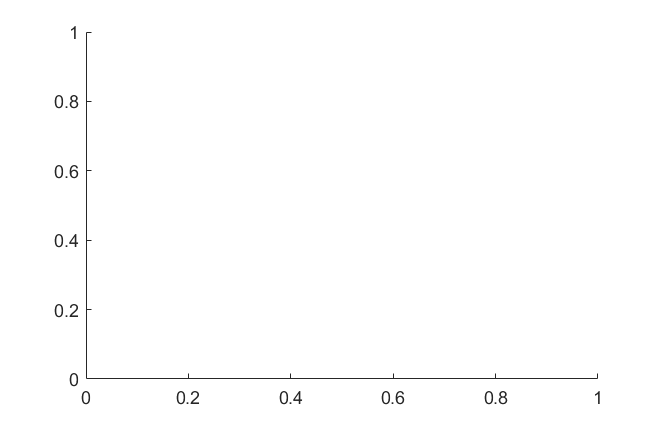


clc,clear,close all
figure("Units","centimeters","Position",[20,10,14,9])
ax = gca;
ax.FontSize = 10.5;

## 生成x y z 数据


t = 1:65000;
x = t;
y = sin(t);
z = sqrt(t);

xlo = 1; xhi = 65000; xSample = 1000;%要显示的x的范围[xlo, xhi], x方向的采样点数量
ylo = -1; yhi = 1; ySample = 1000;%要显示的y的范围[ylo, yhi], y方向的采样点数量
xRange = linspace(xlo,xhi,xSample);
yRange = linspace(ylo,yhi,ySample);
[xq,yq] = meshgrid(xRange,yRange);%% 生成格点
F = scatteredInterpolant(x',y',z');%% 数据比较多时建议使用scatterInterpolant生成插值数据集, 而非griddata
zq = F(xq,yq);%%由x, y, z数据得到格点上的数据

## 格点图

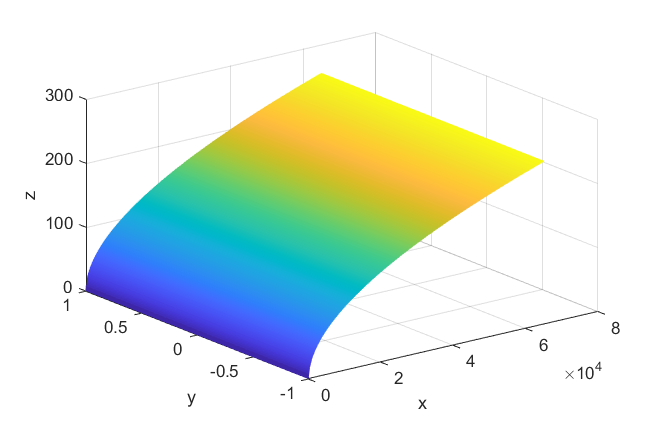


mesh(ax,xq,yq,zq)
xlabel(ax,'x',"FontSize",10.5);
ylabel(ax,'y',"FontSize",10.5);
zlabel(ax,'z',"FontSize",10.5);

## 曲面图

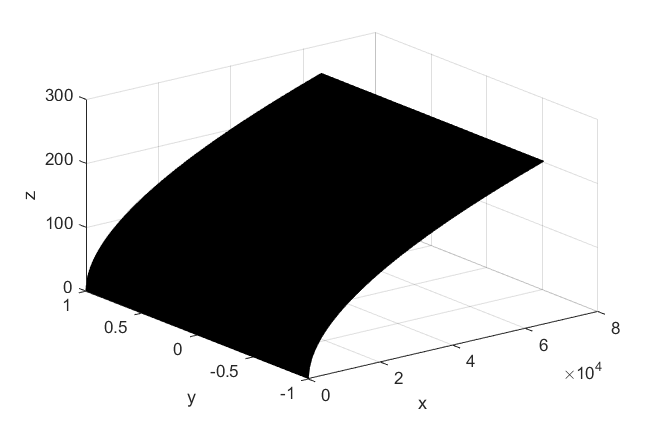


figure("Units","centimeters","Position",[20,10,14,9])
ax = gca;
ax.FontSize = 10.5;
surf(ax,xq,yq,zq)
xlabel(ax,'x',"FontSize",10.5);
ylabel(ax,'y',"FontSize",10.5);
zlabel(ax,'z',"FontSize",10.5);